# Delayed Feedback System for Franka Emika Panda

Add Path

clear;clc;
addpath("..\ReadYAML\")
addpath("Visualization\")
config=ReadYaml("Configuration\FrankaEmikaPanda.yaml");

The system follows


$$M\left(\vec{q} (t)\right) \ddot{\vec{q}} (t) + G \left( \vec{q} (t) \right) = - K_{p} \left( \vec{q} \left( t - \frac{3}{2} t_{s} \right) - \vec{q}_{d} \right) - K_{d} \dot{\vec{q}} \left( t - \frac{3}{2} t_{s} \right) - f \left( \dot{\vec{q}} \right),$$


where friction follows


$$f^{j} (\dot{q})= \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \left( \dot{q}_{j} + \varphi_{3,j} \right)}} - \frac{\varphi_{1,j}}{1 + e^{- \varphi_{2,j} \varphi_{3,j}}}.$$


## Configurations

Dimension

config_mapping.dimension=7;

Precision and truncation rank

config_mapping.precision=30;
config_mapping.trunc_rank=-1;

Target Position

config_mapping.target=config.TargetAngle';

Gains

config_mapping.K_p=diag(config.Kp);
config_mapping.K_d=diag(config.Kd);

Matrix Expontent Method

config_mapping.MatExpOpt="jordan";

Visualization of rank of $\mathcal{A}^i$

config_mapping.visual_Acal_rank=50;

## Discretization

Start Computing M_d
历时 0.001553 秒。
Done
Start Computing K_G
历时 0.191023 秒。
Done
Start Computing K_f
历时 0.001617 秒。
Done
Start Computing A
历时 0.001568 秒。
Done


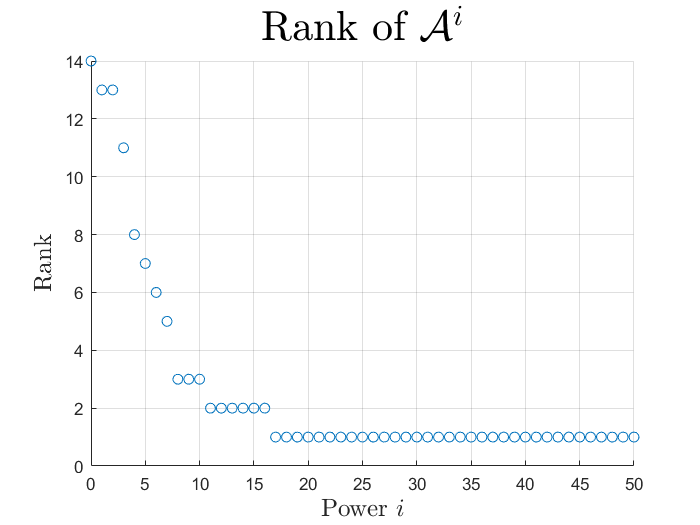

Start Computing B
历时 57.691843 秒。
Done
Start Compiling W
历时 0.001014 秒。
Done


ts=1e-4; % Stable when approximation at 1e-3
% ts=7.87e-3;
result_discretization=DiscreteMapping_rescale(ts,config_mapping);

## Visualization

Eigen Properties

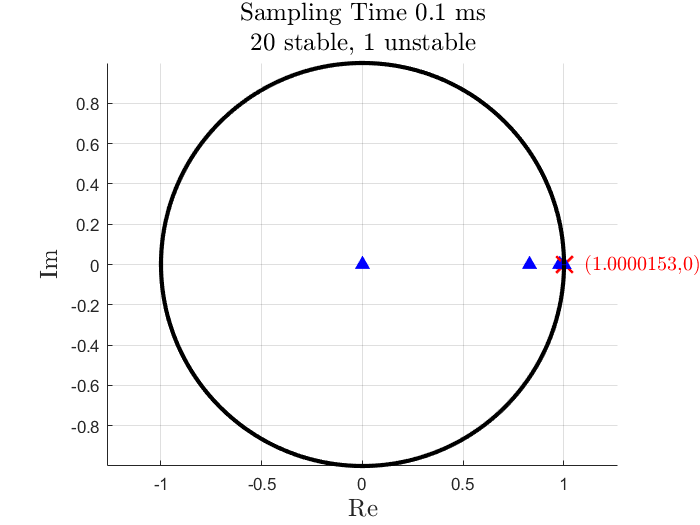

eig_data=eig(result_discretization.W,"balance","vector");
% eig_data=round(eig_data*1000)/1000;
% eig_data=vpa(eig_data,5)
show_eig(eig_data, true, ts)

disp(vpa(eig_data,config_mapping.precision))

$$\left(\begin{array}{c} 0.828965397118038849200161166664\\ 0.978465871853506197197702931589\\ 0.994492323605414174636507596006\\ 0.999947843889985366061523563985+0.000853232938382557414350171320905\,\mathrm{i}\\ 0.999947843889985366061523563985-0.000853232938382557414350171320905\,\mathrm{i}\\ 0.999915846443914180241563371965+0.000770898922822794096208764980105\,\mathrm{i}\\ 0.999915846443914180241563371965-0.000770898922822794096208764980105\,\mathrm{i}\\ 0.999763450852616641917336437473+0.000636984638005043597198950866556\,\mathrm{i}\\ 0.999763450852616641917336437473-0.000636984638005043597198950866556\,\mathrm{i}\\ 0.999679922772755413795664480858+0.000631604115120838771092748320513\,\mathrm{i}\\ 0.999679922772755413795664480858-0.000631604115120838771092748320513\,\mathrm{i}\\ 0.999995895466723516697982176993\\ 1.00001531109649355322233077459\\ 0.999828541130096559719220294937\\ 0.000000528233220938361621146143846939\\ 0.00000038222298098056261022429399947\\ 0.00000034997820591418922796106958685\\ 0.000000347371838300012680686651780904\\ 0.000000032508070738855859699764617142\\ 0.0000000866194784032357418578217827555\\ 0.000000144749311846626541376250501061 \end{array}\right)$$

Norm of $W^i \vec{v}$

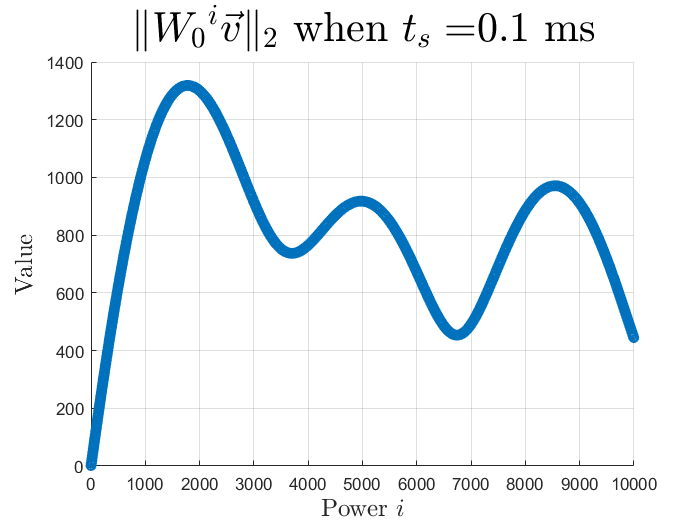

vec_test=0.01*ones(21,1);
modulus_data=zeros(10000,1);
vec_temp=vec_test;
for i=1:length(modulus_data)
    vec_temp=result_discretization.W*vec_temp;
    modulus_data(i)=norm(vec_temp);
end
scatter(1:length(modulus_data),modulus_data)
grid on
title("$\Vert {W_{0}}^{i} \vec{v} \Vert_{2}$ when $t_s=$" + ...
    num2str(1000*ts)+" ms", "FontSize",25,"Interpreter","latex")
xlabel("Power $i$","Interpreter","latex","FontSize",15)
ylabel("Value","Interpreter","latex","FontSize",15)